clc; clear; close all;

%% Modelo numerico em espaco de estados
% Triangulo autoequilibrante com roda de reacao
%
% Estados:
% x1 = theta      [rad]
% x2 = theta_dot  [rad/s]
% x3 = omega      [rad/s]
%
% Entrada:
% u = V           [V]

%% 1) Parametros fisicos da estrutura

m = 0.498;          % massa do corpo [kg]
g = 9.81;           % aceleracao da gravidade [m/s^2]
l = 0.10;           % distancia do eixo de rotacao ao centro de massa [m]

% Momento de inercia aproximado do corpo
I = m*l^2          % [kg.m^2]

I = 0.0050


%% 2) Parametros da roda de reacao

m_w = 0.117;        % massa da roda [kg]
R_w = 0.126;        % raio da roda [m]

% Roda aproximada como disco solido
I_w = 0.5*m_w*R_w^2   % [kg.m^2]

I_w = 9.2875e-04


%% 3) Parametros do motor Nidec 24H - 12 V

V_nom = 12;            % tensao nominal [V]
I_nom = 0.9;           % corrente nominal [A]
tau_nom = 25e-3;       % torque nominal [N.m]
tau_stall = 50e-3;     % torque de travamento [N.m]
rpm_sem_carga = 3900;  % velocidade sem carga [rpm]

omega_sem_carga = rpm_sem_carga*2*pi/60;   % [rad/s]

% Constante eletromecanica estimada
k = V_nom/omega_sem_carga;                 % [V.s/rad]

% Resistencia estimada
r = (k*V_nom)/tau_stall;                   % [ohm]

% Apenas para comparacao
k_torque = tau_nom/I_nom;                  % [N.m/A]

%% 4) Modelo linear em espaco de estados

A = [0           1           0;
     m*g*l/I     0           k^2/(I*r);
     0           0          -k^2/(I_w*r)];

B = [0;
    -k/(I*r);
     k/(I_w*r)];

C = eye(3);
D = zeros(3,1);

sys = ss(A, B, C, D);

%% 5) Exibicao dos parametros e matrizes

disp('Parametros calculados:')

Parametros calculados:


fprintf('I                = %.8f kg.m^2\n', I);

I                = 0.00498000 kg.m^2


fprintf('I_w              = %.8f kg.m^2\n', I_w);

I_w              = 0.00092875 kg.m^2


fprintf('omega_sem_carga  = %.8f rad/s\n', omega_sem_carga);

omega_sem_carga  = 408.40704497 rad/s


fprintf('k                = %.8f V.s/rad\n', k);

k                = 0.02938245 V.s/rad


fprintf('k_torque         = %.8f N.m/A\n', k_torque);

k_torque         = 0.02777778 N.m/A


fprintf('r                = %.8f ohm\n', r);

r                = 7.05178825 ohm



disp(' ')

disp('Matriz A:')

Matriz A:


disp(A)

         0    1.0000         0
   98.1000         0    0.0246
         0         0   -0.1318




disp('Matriz B:')

Matriz B:


disp(B)

         0
   -0.8367
    4.4863




disp('Matriz C:')

Matriz C:


disp(C)

     1     0     0
     0     1     0
     0     0     1




disp('Matriz D:')

Matriz D:


disp(D)

     0
     0
     0




disp('Sistema em espaco de estados:')

Sistema em espaco de estados:


sys


sys =
 
  A = 
            x1       x2       x3
   x1        0        1        0
   x2     98.1        0  0.02458
   x3        0        0  -0.1318
 
  B = 
            u1
   x1        0
   x2  -0.8367
   x3    4.486
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.



%% 6) Modelo aumentado com acao integral
% xi_dot = -omega
%
% xa = [theta; theta_dot; omega; xi]

A_aug = [A              zeros(3,1);
         0   0   -1    0];

B_aug = [B;
         0];

C_aug = eye(4);
D_aug = zeros(4,1);

sys_aug = ss(A_aug, B_aug, C_aug, D_aug);

%% 7) Verificacao de controlabilidade

Co = ctrb(A_aug, B_aug);
posto_Co = rank(Co);
n_estados = size(A_aug,1);

disp('Matriz A aumentada:')

Matriz A aumentada:


disp(A_aug)

         0    1.0000         0         0
   98.1000         0    0.0246         0
         0         0   -0.1318         0
         0         0   -1.0000         0




disp('Matriz B aumentada:')

Matriz B aumentada:


disp(B_aug)

         0
   -0.8367
    4.4863
         0




disp('Posto da matriz de controlabilidade:')

Posto da matriz de controlabilidade:


disp(posto_Co)

     4




disp('Numero de estados do sistema aumentado:')

Numero de estados do sistema aumentado:


disp(n_estados)

     4




if posto_Co == n_estados
    disp('O sistema aumentado e controlavel.')
else
    disp('O sistema aumentado NAO e controlavel.')
end

O sistema aumentado e controlavel.



%% 8) Definicao das matrizes Q e R pela regra de Bryson

theta_max = deg2rad(10);       % [rad]
theta_dot_max = deg2rad(60);   % [rad/s]
omega_max = 255;               % [rad/s]
xi_max = 1000;                 % limite do estado integral

V_max = 12;                    % [V]

Q = diag([1/theta_max^2, ...
          1/theta_dot_max^2, ...
          1/omega_max^2, ...
          1/xi_max^2]);

R = 1/V_max^2;

disp('Matriz Q inicial:')

Matriz Q inicial:


disp(Q)

   32.8281         0         0         0
         0    0.9119         0         0
         0         0    0.0000         0
         0         0         0    0.0000




disp('Matriz R inicial:')

Matriz R inicial:


disp(R)

    0.0069




%% 9) Projeto do controlador LQR continuo

K = lqr(A_aug, B_aug, Q, R);

disp('Ganho K do controlador LQR continuo:')

Ganho K do controlador LQR continuo:


disp(K)

 -263.4017  -28.1135   -0.1281    0.0120




%% 10) Sistema em malha fechada continuo

A_cl = A_aug - B_aug*K;
eig_Acl = eig(A_cl);

disp('Autovalores da malha fechada continua:')

Autovalores da malha fechada continua:


disp(eig_Acl)

 -15.2488 + 0.0000i
  -7.4575 + 0.0000i
  -0.1864 + 0.1082i
  -0.1864 - 0.1082i




if all(real(eig_Acl) < 0)
    disp('O sistema continuo em malha fechada e estavel.')
else
    disp('O sistema continuo em malha fechada NAO e estavel.')
end

O sistema continuo em malha fechada e estavel.



%% 11) Discretizacao do modelo aumentado

Ts = 0.01;   % tempo de amostragem [s]

sys_aug_d = c2d(sys_aug, Ts, 'tustin');

Ad = sys_aug_d.A;
Bd = sys_aug_d.B;
Cd = sys_aug_d.C;
Dd = sys_aug_d.D;

disp('Matriz Ad:')

Matriz Ad:


disp(Ad)

    1.0049    0.0100    0.0000         0
    0.9834    1.0049    0.0002         0
         0         0    0.9987         0
         0         0   -0.0100    1.0000




disp('Matriz Bd:')

Matriz Bd:


disp(Bd)

   -0.0000
   -0.0084
    0.0448
   -0.0002




%% 12) Projeto do controlador LQR discreto

Kd = dlqr(Ad, Bd, Q, R);

disp('Ganho Kd do controlador LQR discreto:')

Ganho Kd do controlador LQR discreto:


disp(Kd)

 -247.8615  -26.3120   -0.1175    0.0107




%% 13) Verificacao dos autovalores em malha fechada discreta

Ad_cl = Ad - Bd*Kd;
eig_Adcl = eig(Ad_cl);

disp('Autovalores da malha fechada discreta:')

Autovalores da malha fechada discreta:


disp(eig_Adcl)

   0.9981 + 0.0011i
   0.9981 - 0.0011i
   0.8585 + 0.0000i
   0.9281 + 0.0000i




if all(abs(eig_Adcl) < 1)
    disp('O sistema discreto em malha fechada e estavel.')
else
    disp('O sistema discreto em malha fechada NAO e estavel.')
end

O sistema discreto em malha fechada e estavel.



%% 14) Validacao numerica da modelagem em malha aberta

eig_A = eig(A);

disp('Autovalores da matriz A em malha aberta:')

Autovalores da matriz A em malha aberta:


disp(eig_A)

    9.9045
   -9.9045
   -0.1318




if any(real(eig_A) > 0)
    disp('O modelo em malha aberta apresenta comportamento instavel.')
else
    disp('O modelo em malha aberta nao apresenta autovalores instaveis.')
end

O modelo em malha aberta apresenta comportamento instavel.


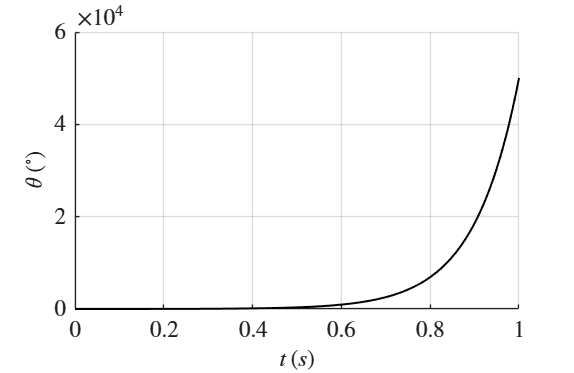


%% Simulacao da resposta livre em malha aberta

t = 0:0.001:1.0;      % tempo de simulacao
u = zeros(size(t));

% Condicao inicial:
% theta(0) = 5 graus
% theta_dot(0) = 0 rad/s
% omega(0) = 0 rad/s
x0 = [deg2rad(5); 0; 0];

[y, t, x] = lsim(sys, u, t, x0);

theta_graus = rad2deg(x(:,1));
theta_dot_graus = rad2deg(x(:,2));
omega_rad = x(:,3);

%% Figura 1 - Angulo theta em malha aberta

hfig = figure;

plot(t, theta_graus, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\theta \, (^\circ)$', 'Interpreter', 'latex');

grid on;

fname = 'validacao_theta_malha_aberta';
picturewidth = 20;
hw_ratio = 0.65;

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

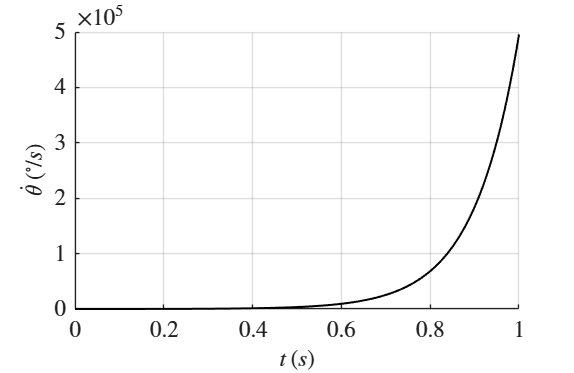



%% Figura 2 - Velocidade angular theta_dot em malha aberta

hfig = figure;

plot(t, theta_dot_graus, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\dot{\theta} \, (^\circ/s)$', 'Interpreter', 'latex');

grid on;

fname = 'validacao_theta_dot_malha_aberta';
picturewidth = 20;
hw_ratio = 0.65;

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

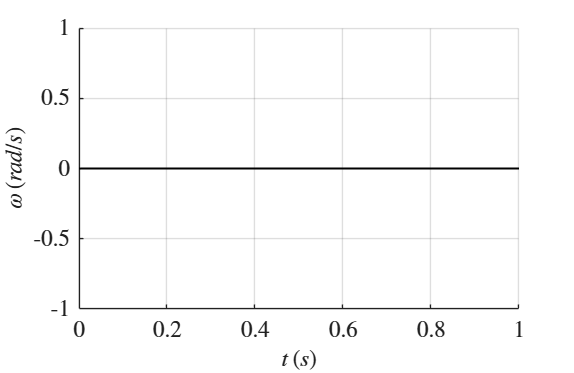



%% Figura 3 - Velocidade angular da roda omega em malha aberta

hfig = figure;

plot(t, omega_rad, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\omega \, (rad/s)$', 'Interpreter', 'latex');

grid on;

fname = 'validacao_omega_malha_aberta';
picturewidth = 20;
hw_ratio = 0.65;

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

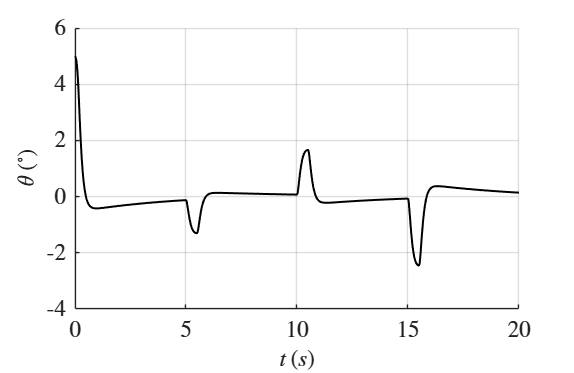


%% 14) Validacao numerica do controlador em malha fechada com disturbios

% Tempo de simulacao
t = 0:Ts:20;      % simulacao de 20 segundos
N = length(t);

% Condicao inicial:
% theta(0) = 5 graus
% theta_dot(0) = 0 rad/s
% omega(0) = 0 rad/s
% xi(0) = 0 rad
x0_cl = [deg2rad(5); 0; 0; 0];

% Inicializacao dos vetores
x_cl = zeros(4, N);
u_cl = zeros(1, N);
d_cl = zeros(1, N);

x_cl(:,1) = x0_cl;

%% Definicao dos disturbios aplicados na entrada

for k = 1:N
    if t(k) >= 5 && t(k) < 5.5
        d_cl(k) = 3;      % disturbio positivo de 3 V
    elseif t(k) >= 10 && t(k) < 10.5
        d_cl(k) = -4;     % disturbio negativo de -4 V
    elseif t(k) >= 15 && t(k) < 15.5
        d_cl(k) = 6;      % disturbio positivo de 6 V
    end
end

%% Simulacao discreta em malha fechada com disturbios

for k = 1:N-1

    % Lei de controle LQR discreta
    u_cl(k) = -Kd*x_cl(:,k);

    % Saturacao da tensao de controle
    if u_cl(k) > 12
        u_cl(k) = 12;
    elseif u_cl(k) < -12
        u_cl(k) = -12;
    end

    % Atualizacao dos estados com disturbio somado na entrada
    x_cl(:,k+1) = Ad*x_cl(:,k) + Bd*(u_cl(k) + d_cl(k));
end

% Ultimo valor de controle
u_cl(N) = -Kd*x_cl(:,N);

if u_cl(N) > 12
    u_cl(N) = 12;
elseif u_cl(N) < -12
    u_cl(N) = -12;
end

%% Conversao dos estados para graficos

theta_cl_graus = rad2deg(x_cl(1,:));
theta_dot_cl_graus = rad2deg(x_cl(2,:));
omega_cl = x_cl(3,:);
xi_cl = x_cl(4,:);

%% Figura 1 - Angulo theta em malha fechada

hfig = figure;

plot(t, theta_cl_graus, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\theta \, (^\circ)$', 'Interpreter', 'latex');

grid on;

fname = 'validacao_theta_malha_fechada';
picturewidth = 20;
hw_ratio = 0.65;

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

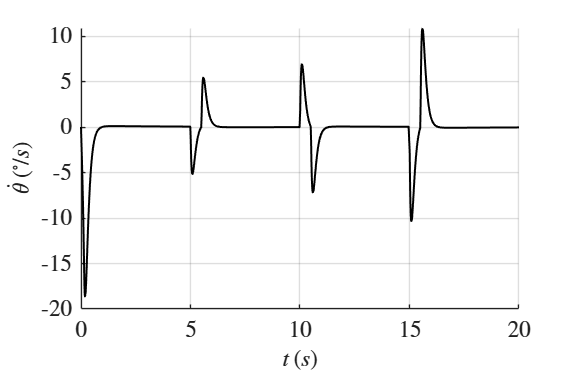



%% Figura 2 - Velocidade angular theta_dot em malha fechada

hfig = figure;

plot(t, theta_dot_cl_graus, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\dot{\theta} \, (^\circ/s)$', 'Interpreter', 'latex');

grid on;

fname = 'validacao_theta_dot_malha_fechada';
picturewidth = 20;
hw_ratio = 0.65;

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

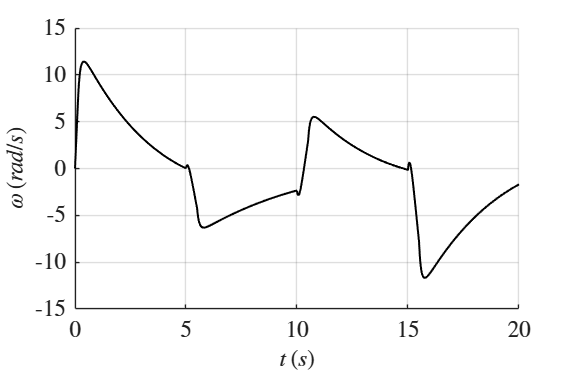



%% Figura 3 - Velocidade angular da roda omega em malha fechada

hfig = figure;

plot(t, omega_cl, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\omega \, (rad/s)$', 'Interpreter', 'latex');

grid on;

fname = 'validacao_omega_malha_fechada';
picturewidth = 20;
hw_ratio = 0.65;

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

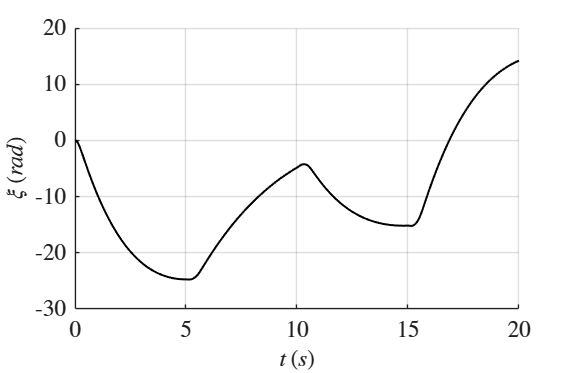



%% Figura 4 - Estado integral xi em malha fechada

hfig = figure;

plot(t, xi_cl, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\xi \, (rad)$', 'Interpreter', 'latex');

grid on;

fname = 'validacao_xi_malha_fechada';
picturewidth = 20;
hw_ratio = 0.65;

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

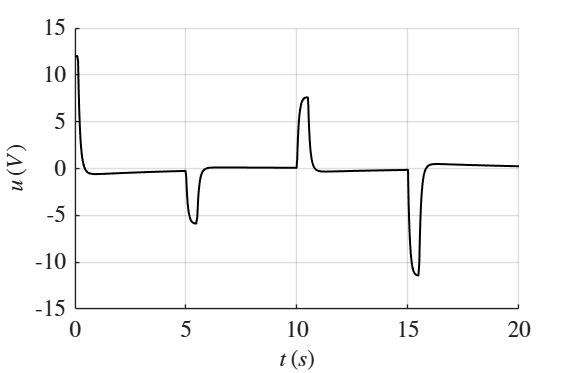



%% Figura 5 - Sinal de controle em malha fechada

hfig = figure;

plot(t, u_cl, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$u \, (V)$', 'Interpreter', 'latex');

grid on;

fname = 'validacao_controle_malha_fechada';
picturewidth = 20;
hw_ratio = 0.65;

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

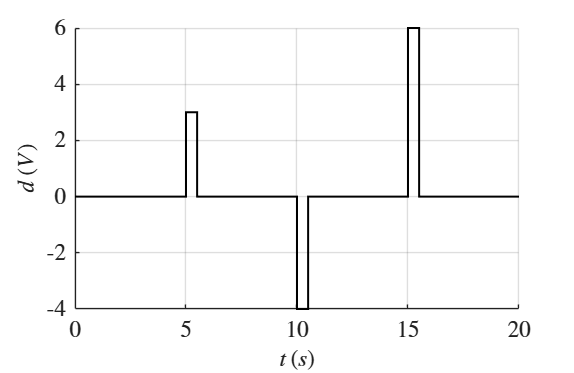



%% Figura 6 - Disturbios aplicados

hfig = figure;

stairs(t, d_cl, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$d \, (V)$', 'Interpreter', 'latex');

grid on;

fname = 'validacao_disturbios_malha_fechada';
picturewidth = 20;
hw_ratio = 0.65;

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')